# Eksamensæt

**M3NUM1 Anvendte Numeriske Metoder -- 16-01-2023**

**Mathias Bruun Houmøller -- 202006837 -- Au666097**

## Opgave 1

clear
format short %formater resultater til 4 decimaler

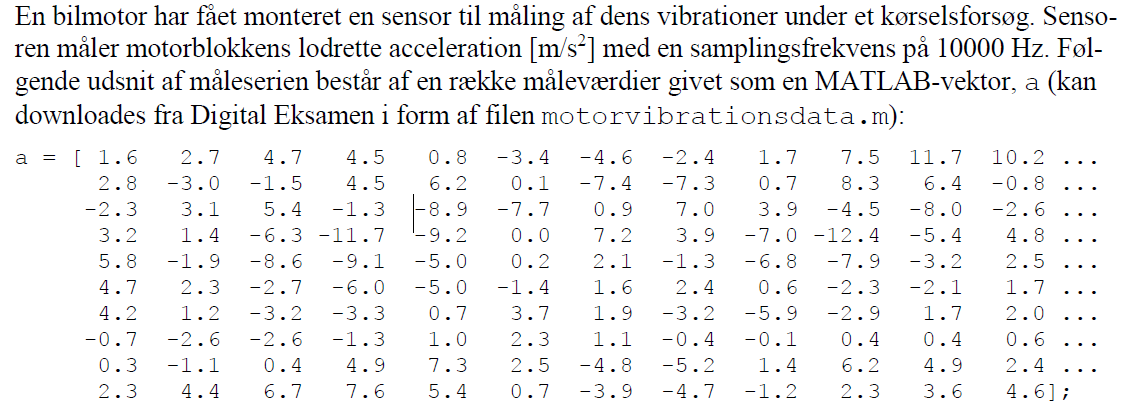

### (1a)

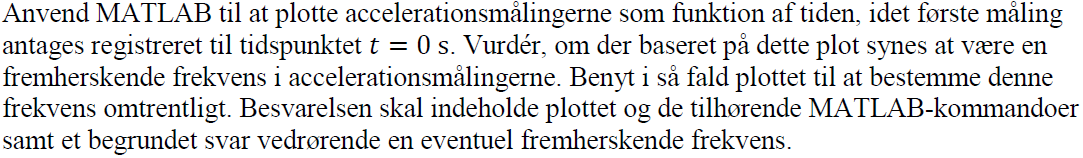

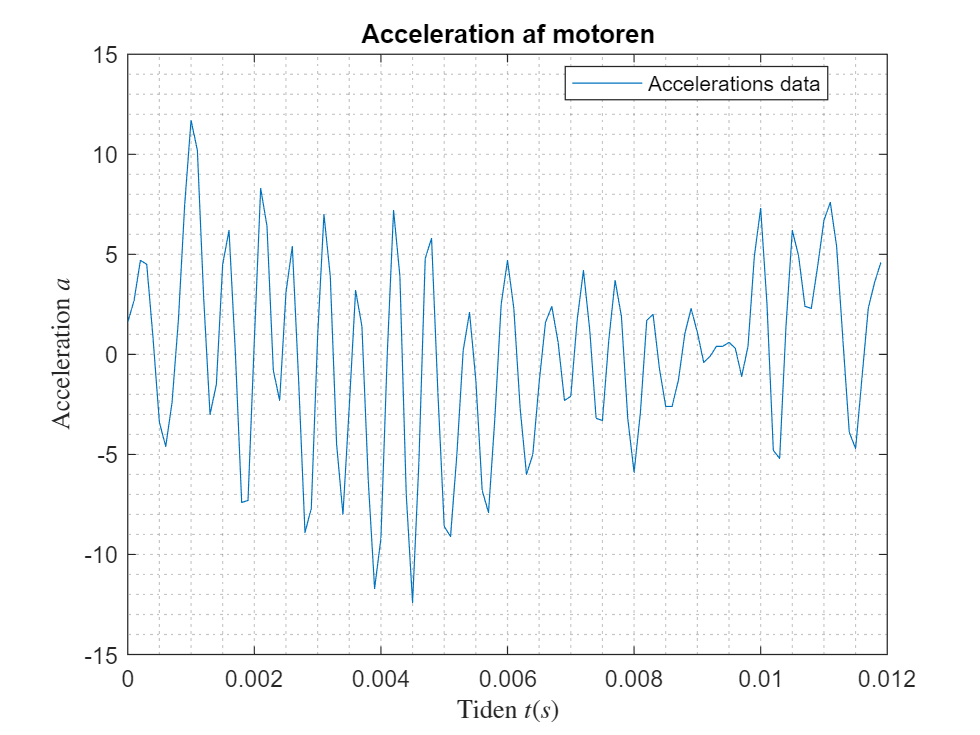

motorvibrationsdata;
dt = 1e-4; % Samplingsinterval (s)
t = 0: dt :(length(a)-1)*dt; %der laves data for tiden
% her trækkes fra og divideres for at få den rigtige dimention.

plot(t,a, 'DisplayName', 'Accelerations data') %data plottes

% formalier
legend('location', 'best')
title('Acceleration af motoren')
xlabel('Tiden $t(s)$', 'interpreter', 'latex')
ylabel('Acceleration $a$', 'interpreter', 'latex')
grid('minor')

Der tælles 20 toppe fra 0 til 0,012 sekunder dermed får vi $f = \frac{20}{0,012} = 1666,7\ Hz$

format long
20/0.012

ans =      1.666666666666667e+03


### (1b)

Bestem den dominerende frekvens i serien af accelerationsmålinger ud fra tidsseriens powerspek-trum. Anfør i besvarelsen den dominerende frekvens samt de MATLAB-kommandoer og –resulta-ter, der har dannet grundlag for bestemmelsen af denne frekvens.

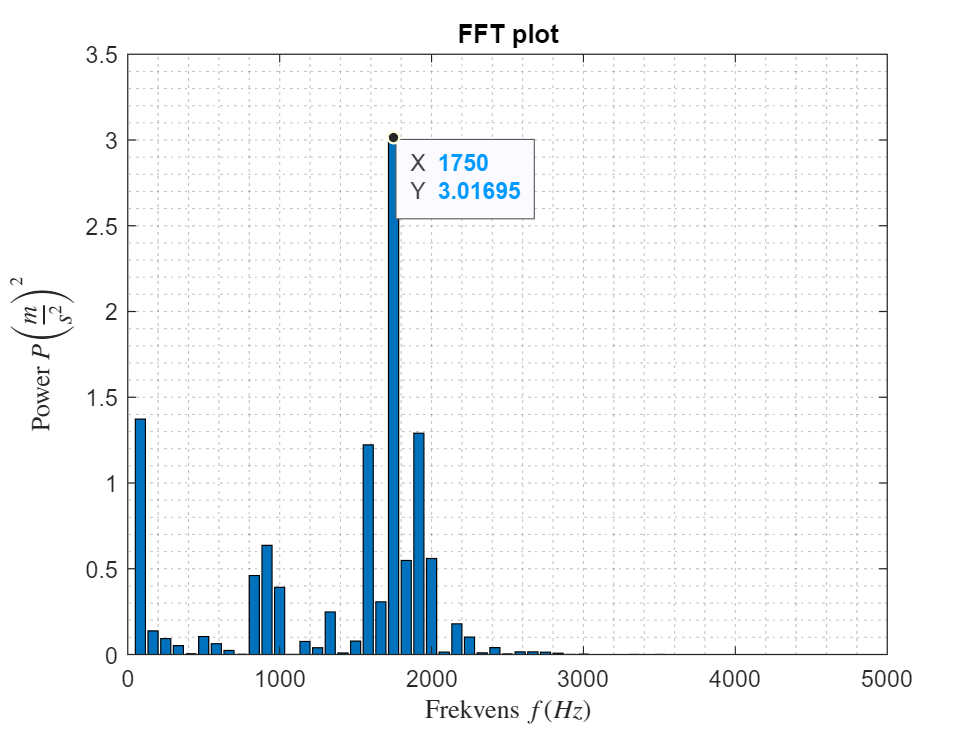

n = length(a);              % Antal samplinger % her vælges alt data som sample
T = n*dt;                   % Signallængde (s) % Tiden det tager at køre smplet igennem
A = fft(a)/n;               % FFT af a (mm)
fs = 1/dt;                  % Samplingsfrekvens (Hz) %Frekvensen hvormed der tages sampels
fmax = fs/2;                % Maks frekvens (Hz)
df = 1/T;                   % Frekvensstep (Hz)
f = (0:n-1)*df;             % Frekvensvektor (Hz) % alle frekvensskridt der gennemgåes
P = real(A).^2 + imag(A).^2;% Powervektor (mm^2) % Her lægges real delen og imaginær delens sammen og forstærkes så de kun er positive
bar(f,P);                   % Plot af powerspektrum %plottes som barplot for bedre overskuelighed
xlim([0 fmax]);             % Afgræns frekvensakse % så der kun ses på et område der ikke gentager en frekvens

% Formalier
title('FFT plot')
xlabel('Frekvens $f(Hz)$', 'interpreter', 'latex')
ylabel('Power $P \left( \frac{m}{s^2} \right)^2 $', 'interpreter', 'latex')
grid('minor')

ax = gca;
chart = ax.Children(1);
datatip(chart,1750,3.017);

result = find(P==max(P)) % vi finder postionen i power vektoren hvor den største frekvens viser sig

result =     22   100


% Her vælges første tal da andet tal blot af en gentagelse af frekvensen
% Vi kan nu finde frekvensen for det stærkeste signam
f_strong = f(22)

f_strong =         1750


**Den dominerende frekvens findes nu til **$1750Hz$**.**

### (1c)

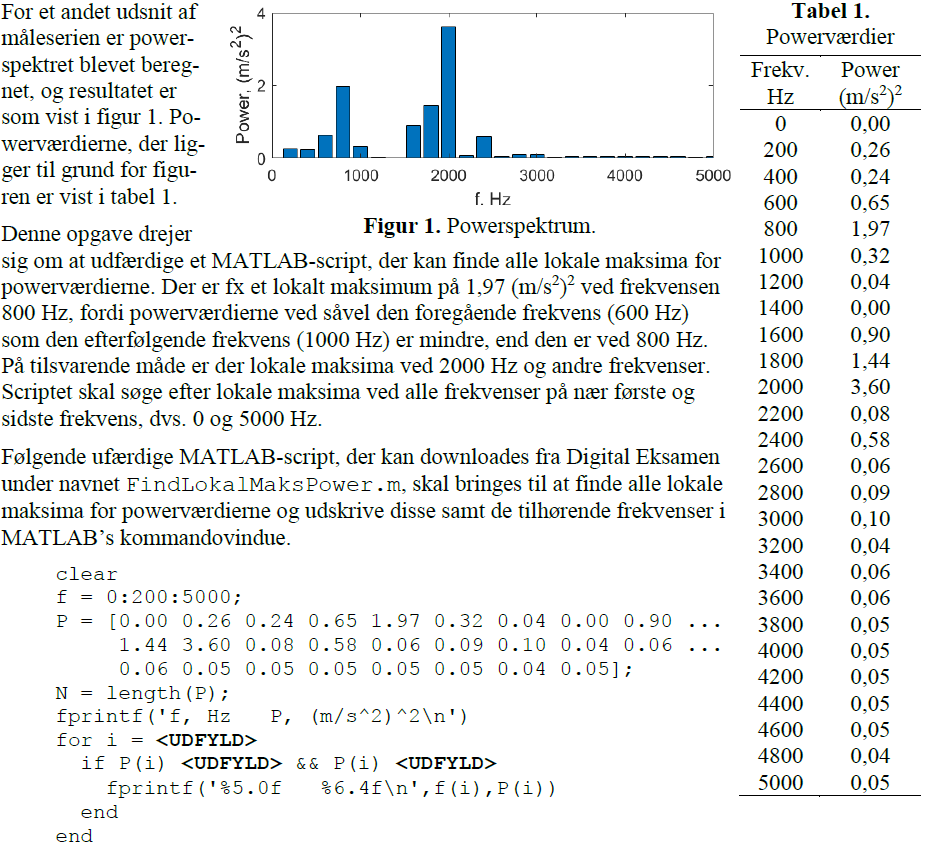

clear
f = 0:200:5000;
P = [0.00 0.26 0.24 0.65 1.97 0.32 0.04 0.00 0.90 ...
    1.44 3.60 0.08 0.58 0.06 0.09 0.10 0.04 0.06 ...
    0.06 0.05 0.05 0.05 0.05 0.05 0.04 0.05];
N = length(P);
fprintf('f, Hz P, (m/s^2)^2\n')

f, Hz P, (m/s^2)^2


for i = 2:N-1
    if P(i) > P(i-1) && P(i) > P(i+1)
        fprintf('%5.0f %6.4f\n',f(i),P(i))
    end
end

  200 0.2600
  800 1.9700
 2000 3.6000
 2400 0.5800
 3000 0.1000


Således findes 5 lokale maximaer og deres styrke, det ses at ved 3000 Hz er den ret lille.

## Opgave 2

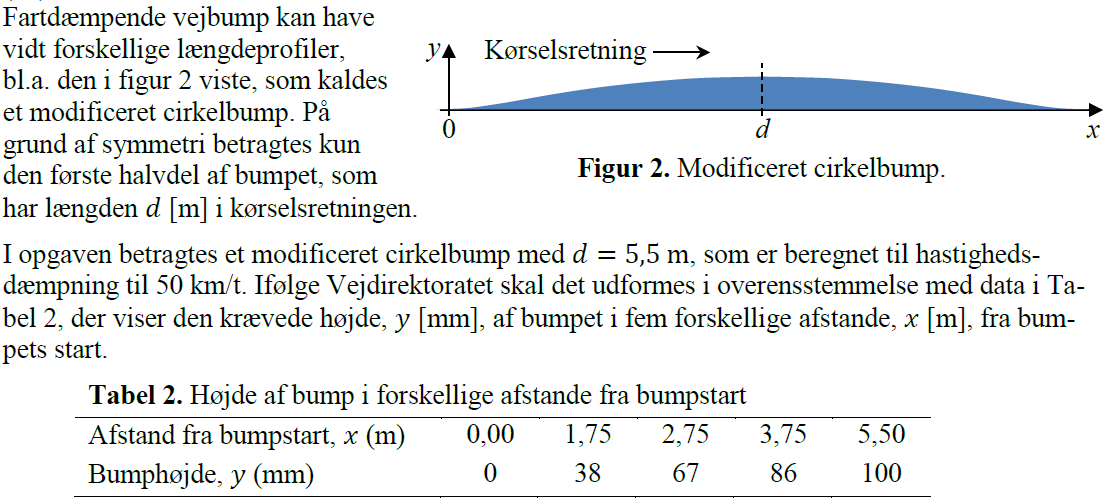

clear

### (2a)

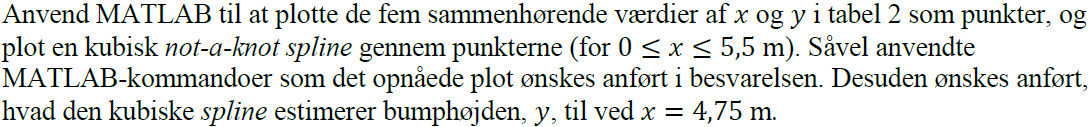

### (2b)

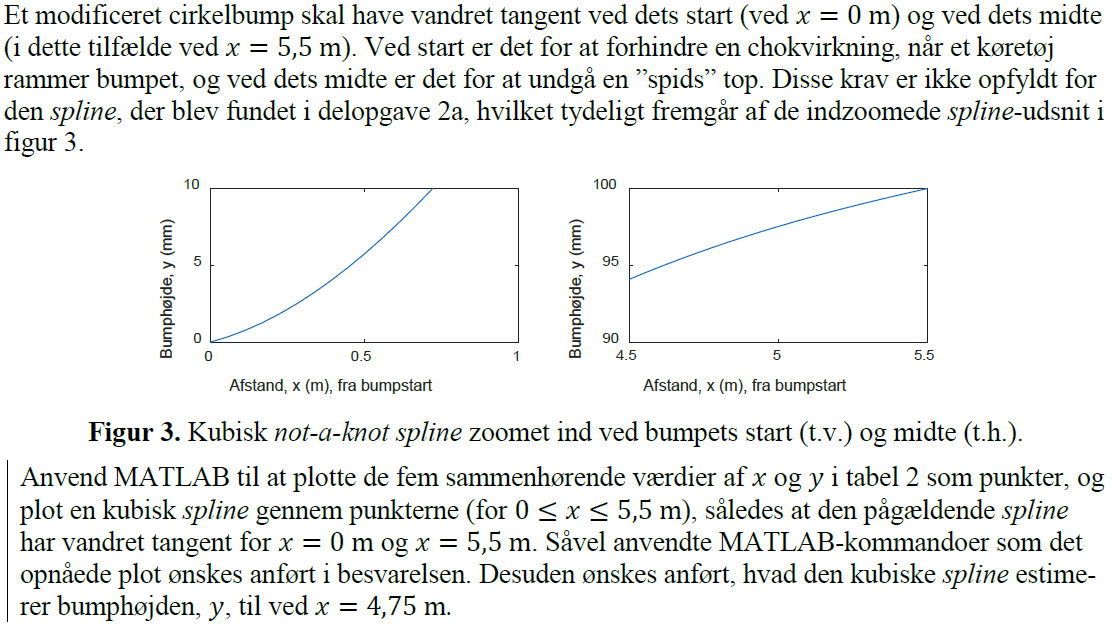

### (2c)

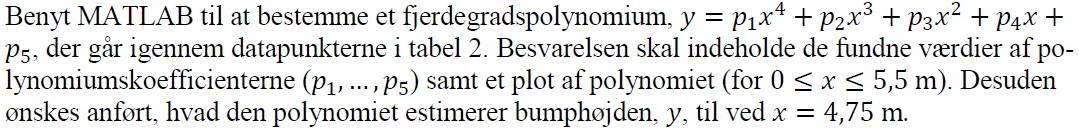

## Opgave 3

clear
u = symunit;

### (3a)

### (3b)

### (3c)

### (3d)

## Opgave 4

clear
u = symunit;

### (4a)

### (4b)

### (4c)

### (4d)

## Plot koder

% %der plottes
% fplot(f(x),[-4, 5], 'DisplayName', 'funktion') %data plottes
% hold on
% yline(0, '--', 'DisplayName', '0-linje')
% xline([-3], 'g--', 'DisplayName', 'Rødder'); 
% xline([0 4], 'g--','HandleVisibility','off');
% 
% % formalier
% legend('location', 'best')
% title('Kontinuert funktion', 'interpreter', 'latex')
% xlabel('$x$', 'interpreter', 'latex')
% ylabel('$f(x)$', 'interpreter', 'latex')
% grid('minor')
% hold off